# Task 1

table_data = readtable('ContestData.txt');

data = table2array(table_data(:,8));
fignum = 0

fignum = 0

fignum = fignum + 1

fignum = 1

figure(fignum)
clf
plot(data,'.-')
hold on
xlabel('t')
ylabel('y(t)')
title('time series with trend and seasonality')

** task1.a**

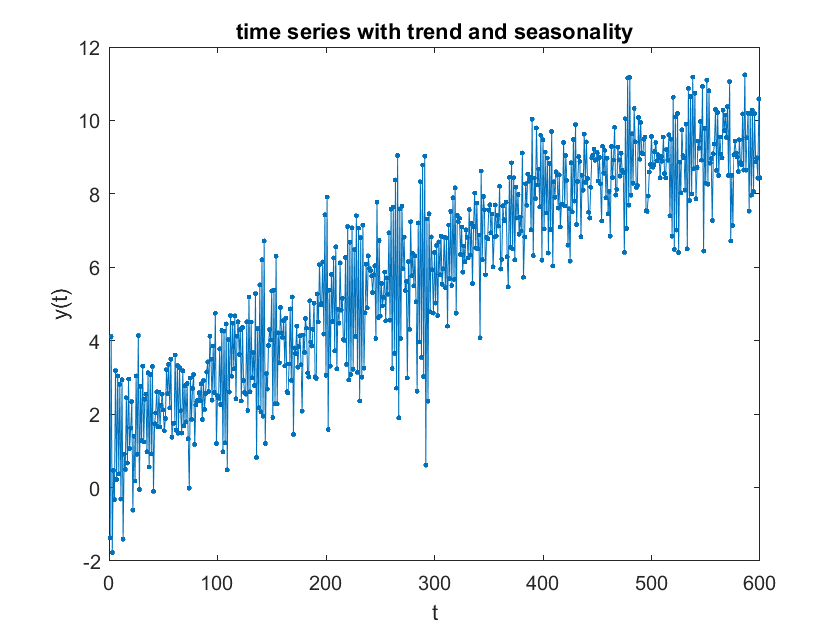

%%%%%% 1.a) Remove trend using a moving average filter

maorder = input('Remove trend: Give an order for the moving average filter: > ');

mv = movingaveragesmooth2(data,maorder);
fignum = fignum + 1 

fignum = 2

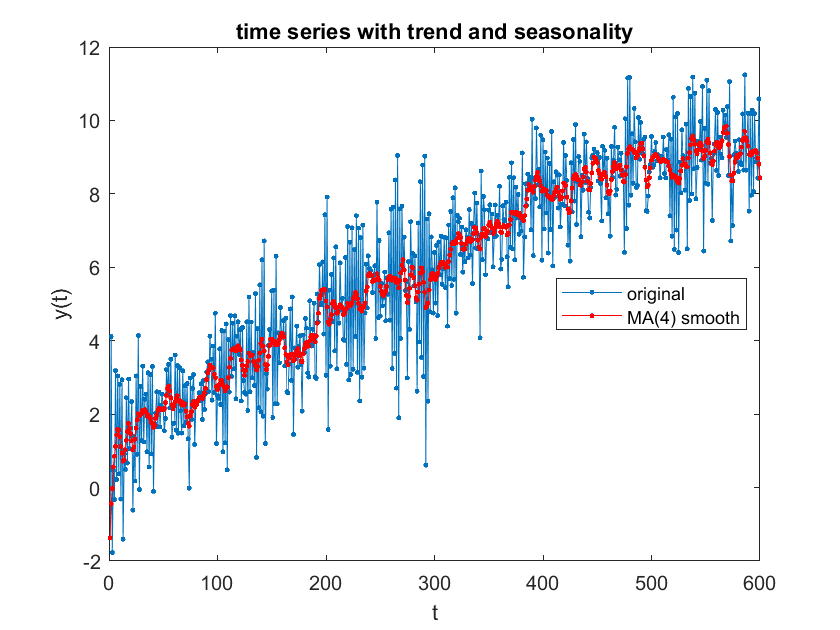

figure(fignum)
clf
plot(data,'.-')
hold on
plot(mv,'.-r')
xlabel('t')
ylabel('y(t)')
title('time series with trend and seasonality')
legend('original',sprintf('MA(%d) smooth',maorder),'Location','Best')


data_mAv = data - mv;
fignum = fignum + 1

fignum = 3

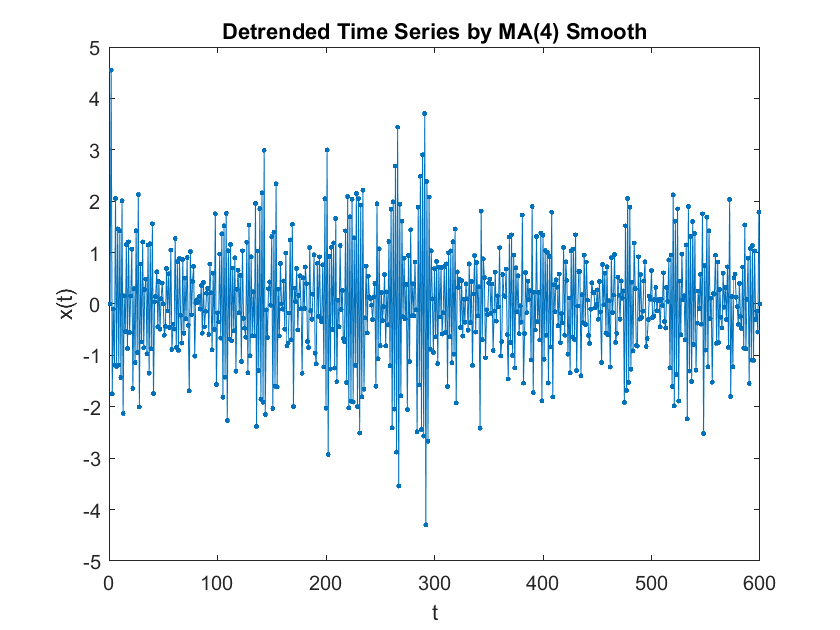

figure(fignum)
clf
plot(data_mAv,'.-')
xlabel('t')
ylabel('x(t)')
title(sprintf('Detrended Time Series by MA(%d) Smooth',maorder))

**task 1.b**

% Detrend using the method of first differences
data_firstDif = diff(data);

% Plot original and detrended time series
fignum = fignum + 1

fignum = 4

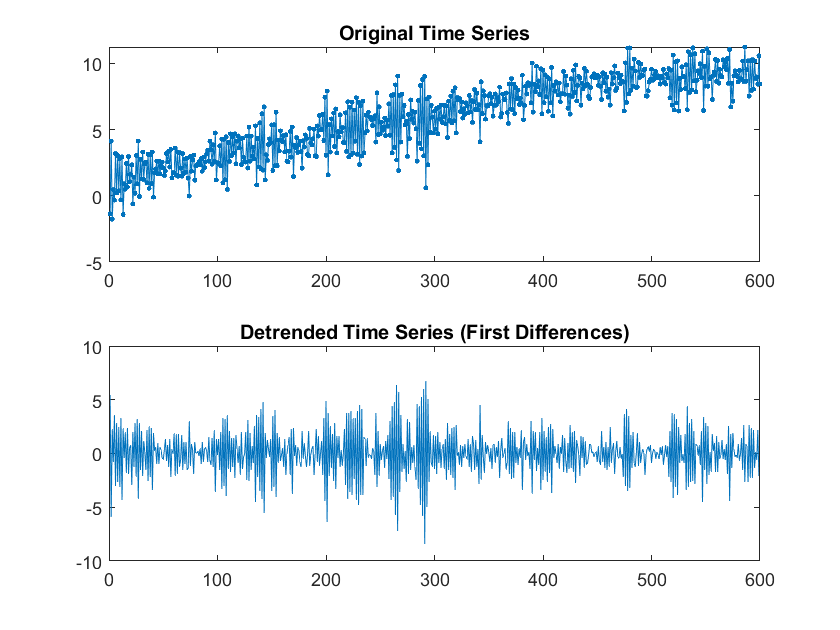


figure(fignum);
subplot(2,1,1);
plot(data,'.-');
title('Original Time Series');

subplot(2,1,2);
plot(data_firstDif);
title('Detrended Time Series (First Differences)');

**task 2**

maxtau = 100;
alpha = 0.05;
zalpha = norminv(1-alpha/2)

zalpha = 1.9600

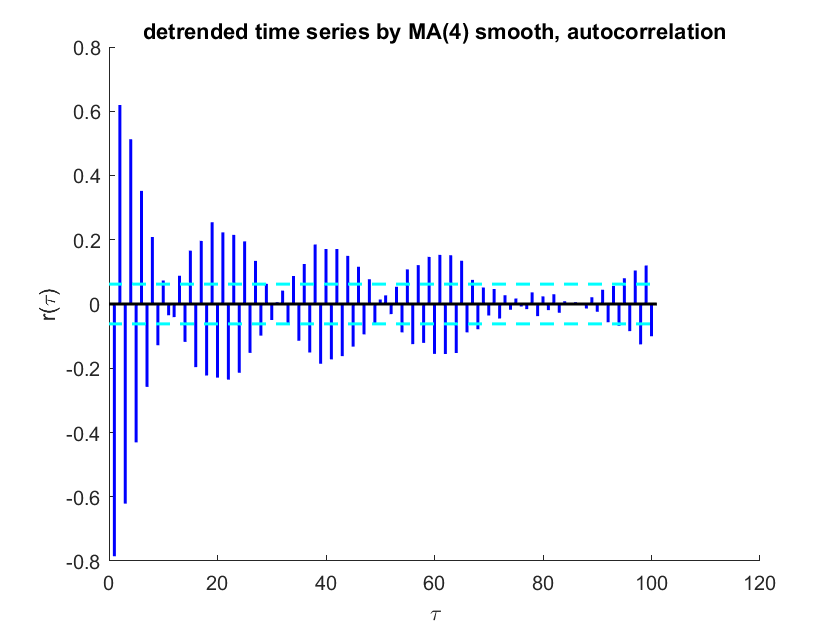

autlim = zalpha/sqrt(n);

%% If we detrend the data using the moving average filter

% autocorrelation of the detrended data
aCorr = autocorrelation(data_mAv, maxtau);

fignum = fignum +1;
figure(fignum)

hold on
for i=1:maxtau
    plot(aCorr(i+1,1)*[1 1],[0 aCorr(i+1,2)],'b','linewidth',1.5)
end
plot([0 maxtau+1],[0 0],'k','linewidth',1.5)
plot([0 maxtau+1],autlim*[1 1],'--c','linewidth',1.5)
plot([0 maxtau+1],-autlim*[1 1],'--c','linewidth',1.5)
xlabel('\tau')
ylabel('r(\tau)')
title(sprintf('detrended time series by MA(%d) smooth, autocorrelation',maorder))

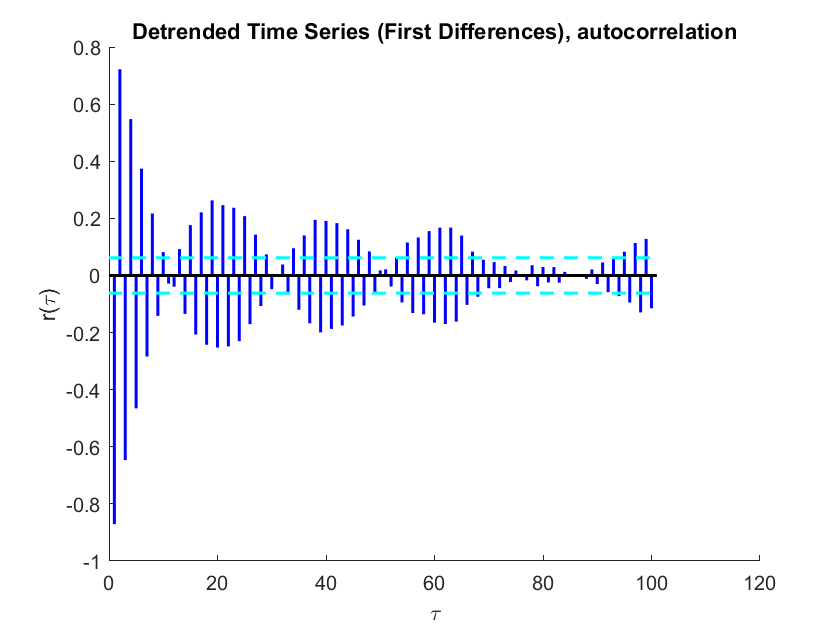




%% If we detrend using first differences

% autocorrelation of the detrended data
aCorr = autocorrelation(data_firstDif, maxtau);

fignum = fignum +1;
figure(fignum)

hold on
for i=1:maxtau
    plot(aCorr(i+1,1)*[1 1],[0 aCorr(i+1,2)],'b','linewidth',1.5)
end
plot([0 maxtau+1],[0 0],'k','linewidth',1.5)
plot([0 maxtau+1],autlim*[1 1],'--c','linewidth',1.5)
plot([0 maxtau+1],-autlim*[1 1],'--c','linewidth',1.5)
xlabel('\tau')
ylabel('r(\tau)')
title(sprintf('Detrended Time Series (First Differences), autocorrelation'))